% Author: Wei Zhou
% Institution: Department of Mechanical and Materials Engineering, 
% University of Cincinnati, Cincinnati, OH 45221, USA
% Year: 2022
% Version: 2.0
% Reference: Empirical Fourier decomposition: An accurate signal decomposition method
% for nonlinear and non-stationary time series analysis
% https://doi.org/10.1016/j.ymssp.2021.108155
% =========================================================================

**Signal generation**

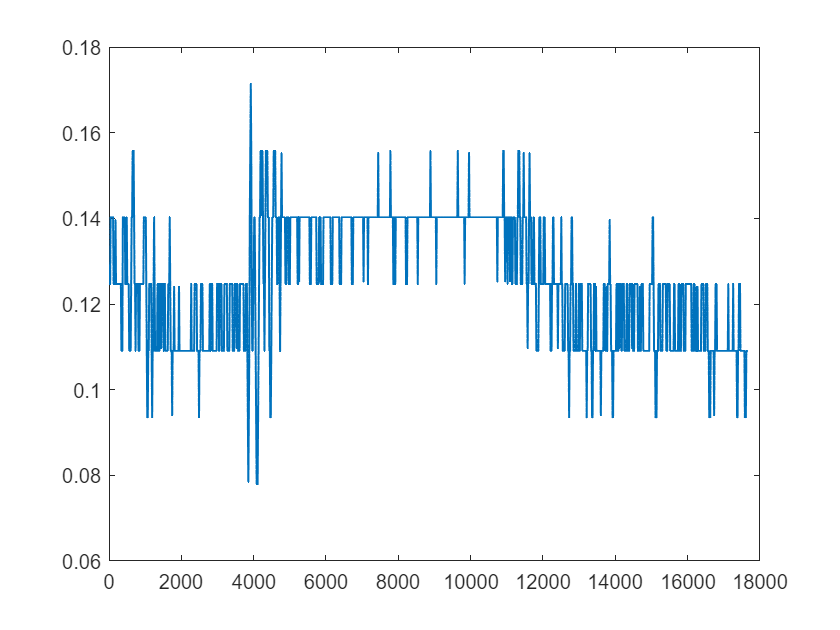

clear; clc; close all
set(0,'defaultlinelinewidth',1)
%T = 1;          % total time
fs = 2000;      % sample frequency
%t = (0:1/fs:T); % time step
%f31 = 1./(1.2+cos(2*pi*t));
%f12 = 2*cos(8*pi*t);
%f32 = cos(32*pi*t+0.2*cos(64*pi*t))./(1.2+sin(2*pi*t));
sig3 = readtable('exa.csv');
% plot
figure
x = sig3{:, 1};
y = sig3{:, 2};
plot(x, y)

**Using EFD to decompose**

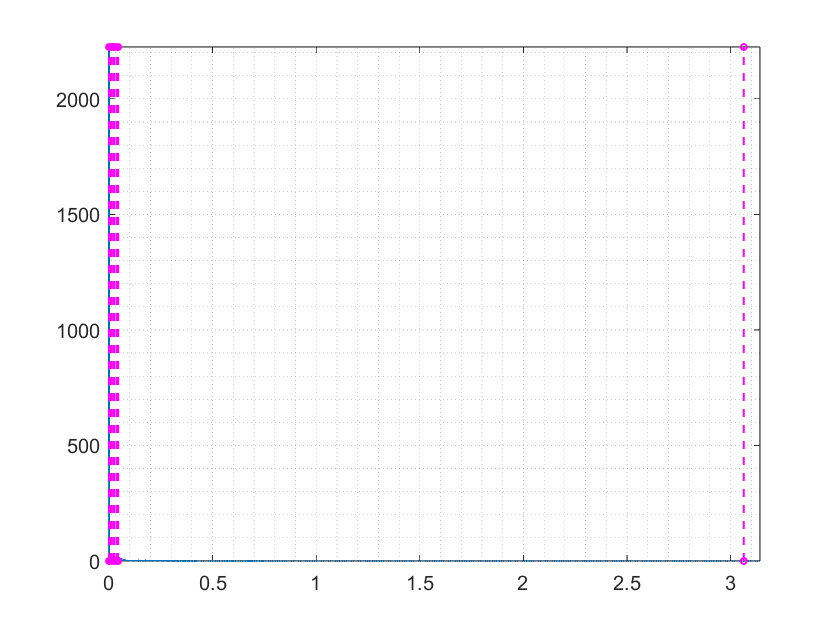

% the sig3 consists of 10 components, so 10 segments are needed
N = 10;
% perform EFD
[efd,cerf,boundaries] = EFD(y, N);
% plot the detected boundaries, to check the segmentation results
plotbounds(y,boundaries); grid minor

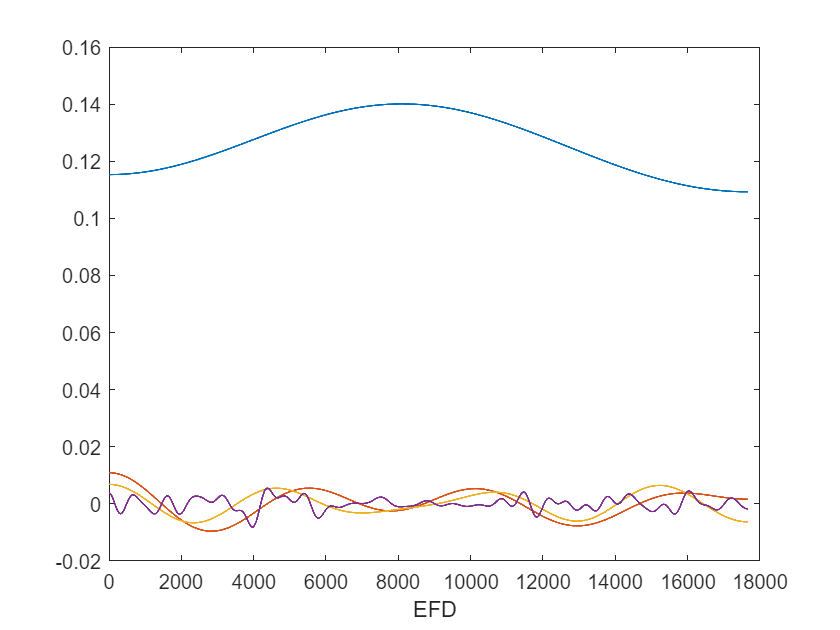

% two components
figure

plot(x,efd{1,1}); grid minor
hold on 
plot(x,efd{2,1}); grid minor
hold on 
plot(x,efd{3,1}); grid minor
hold on 
plot(x,efd{4,1}); grid minor
hold on 

xlabel('EFD')

**TFR Results**

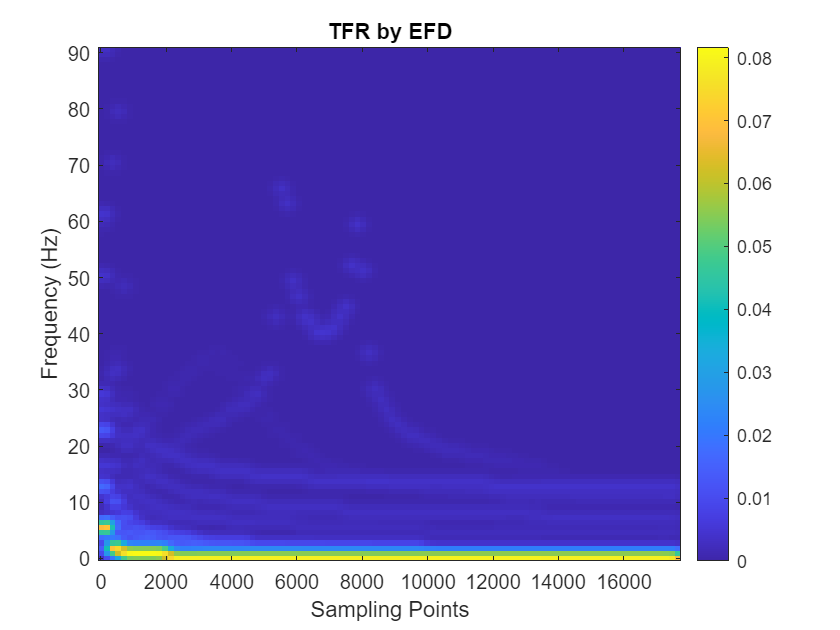


%ff = [f1;f2];
for i = 1:N
    
    [inst_fre(i,:), inst_amp(i,:)] = IFIA(efd{i},fs);
    %[inst_fre_ben(i,:), inst_amp_ben(i,:)] = IFIA(ff(i,:),fs);
end

[nt,tscale,fscale] = Plot_TFR(inst_fre(:,1:100)',inst_amp(:,1:end)',x); % magnitude value
q = fspecial('gaussian',7,0.6);
nsu = filter2(q,nt);
nsu = filter2(q,nsu);
figure; imagesc(tscale,fscale,nsu.^.5); colorbar; axis xy;
xlabel('Sampling Points'); ylabel('Frequency (Hz)'); title('TFR by EFD')